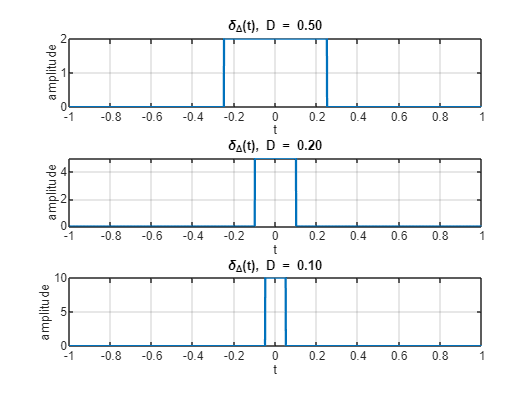


s     = @(t)   (t >= 0).*t;                       % rampa unidade
uD    = @(t,D) (1./D) .* (s(t + D/2) - s(t - D/2));  % step "suave" u_Δ
duD   = @(t,D,h) (uD(t+h/2,D) - uD(t-h/2,D)) ./ h;   % derivada numérica
deltaD = @(t,D) duD(t,D,1e-6);                       % impulso aproximado

t = -1:0.0005:1;

figure;
Ds = [0.5, 0.2, 0.1];
for i = 1:length(Ds)
    D = Ds(i);
    subplot(length(Ds),1,i);
    plot(t, deltaD(t,D), 'LineWidth', 1.5);
    grid on;
    title(sprintf('\\delta_{\\Delta}(t), D = %.2f', D));
    xlabel('t'); ylabel('amplitude');
end